Resize and pad all photos to 512 x 512

data = batchcropIm('data');

PASSED:/home/echo/bolete/data/alessioporus-rubriflavus/Alessioporus-rubriflavus-chemicals-on-cap-Igor-Safonov.jpeg
PASSED:/home/echo/bolete/data/alessioporus-rubriflavus/Alessioporus-rubriflavus-stretched-netting-Jason-Bolin.jpg
PASSED:/home/echo/bolete/data/aureoboletus-abruptibulbus/Aureoboletus-auriporus-Richard-and-Danielle-KnealMO-99902.jpeg
PASSED:/home/echo/bolete/data/aureoboletus-auriporus/Boletus-auriporus1.jpg
PASSED:/home/echo/bolete/data/aureoboletus-flaviporus/Aureoboletus-flaviporus-pores-Darv-DeShazer.jpg
PASSED:/home/echo/bolete/data/aureoboletus-flaviporus/Boletus-flaviporus-Alan-Rockefeller.jpg
PASSED:/home/echo/bolete/data/aureoboletus-gentilis/Boletus-carminiporus-halves-Ryan-Patrick-MO-244944.jpeg
PASSED:/home/echo/bolete/data/aureoboletus-innixus/Boletus-innixus-cluster-Fluff-Berger.jpeg
PASSED:/home/echo/bolete/data/aureoboletus-mirabilis/Aureoboletus-mirabilis-Darv-DeShazer-scaled.jpg
PASSED:/home/echo/bolete/data/aureoboletus-russellii/Aureoboletus-russellii-G

Gather corresponding labels for each image

names = data.fileName;
newNames = string.empty(length(names),0);
for i=1:length(names)
    sp = split(names{i},'/');
    newNames(i) = string(sp{6});
end
newNames = parseNames(newNames);
data.name = newNames;

labels = readtable('clean_data/labels.csv');
ids = zeros([height(data),1]);
realNames = labels.NewName;
for i = 1:height(data)
    idx = find(newNames(i) == realNames);
    if isempty(idx)
        disp(data.fileName(i));
    else
        ids(i) = labels.ID(idx);
    end
end
data.id = ids;
data = sortrows(data, "id");

Join labels table to images for other labels type

joined = join(data, labels, "LeftKeys","id", "RightKeys","ID", "LeftVariables","id");

Display and count image data

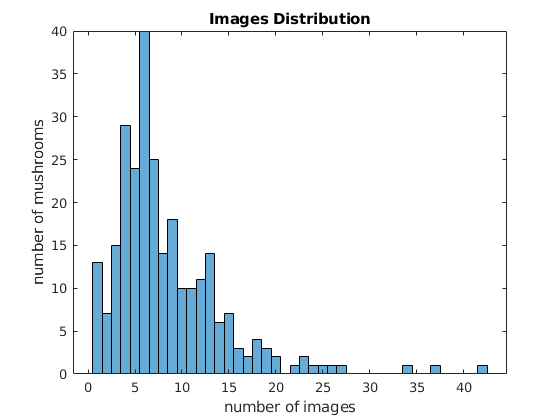

h = histcounts(ids, length(unique(ids)));
[c, idx] = sort(h);
histogram(c)
xlabel("number of images")
ylabel("number of mushrooms")
title("Images Distribution")

writetable(t(:,"id"), 'clean_data/image_cts.csv')

Create H5 dataset

s = size(data.im{1});
sz = [Inf, s];
h5create('bolete.h5', '/bolete-images', sz, "Datatype","uint8","ChunkSize", [1 s])

Write images to dataset file

N = height(data);
d = zeros(N,s(1), s(2), s(3), "uint8");
ims = data.im;
parfor i = 1:N
    d(i,:,:,:) = ims{i};
end
h5write("bolete.h5",'/bolete-images', d, [1, 1, 1, 1], [N, s])

Write labels to dataset file

ids = uint64(data.id);

ids = 2244×1 uint64 column vector
   1
   1
   1
   1
   1
   1
   1
   1
   1
   1


h5create('bolete.h5', '/bolete-labels', Inf, "Datatype","uint64","ChunkSize", 1)
h5write("bolete.h5", '/bolete-labels', ids, 1, N)

joined = 2244×54 table
    id               NewName                                Name                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                 Images                                                                      

Write features to file

vars = joined.Properties.VariableNames;

vars = 1×54 cell array
    {'id'}    {'NewName'}    {'Name'}    {'Images'}    {'F1'}    {'F2'}    {'F3'}    {'F4'}    {'F5'}    {'F6'}    {'F7'}    {'F8'}    {'F9'}    {'F10'}    {'F11'}    {'F12'}    {'F13'}    {'F14'}    {'F15'}    {'F16'}    {'F17'}    {'F18'}    {'F19'}    {'F20'}    {'F21'}    {'F22'}    {'F23'}    {'F24'}    {'F25'}    {'F26'}    {'F27'}    {'F28'}    {'F29'}    {'F30'}    {'F31'}    {'F32'}    {'F33'}    {'F34'}    {'F35'}    {'F36'}    {'F37'}    {'F38'}    {'F39'}    {'F40'}    {'F41'}    {'F42'}    {'F43'}    {'F44'}    {'F45'}    {'F46'}    {'F47'}    {'F48'}    {'F49'}    {'F50'}


characteristics = joined{:, vars(5:end-5)};
chars = uint8(characteristics);

chars = 2244×45 uint8 matrix
   1   0   0   1   0   1   1   0   0   1   1   0   0   0   0   1   0   0   1   0   0   0   0   1   1   0   1   0   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   1
   1   0   0   1   0   1   1   0   0   1   1   0   0   0   0   1   0   0   1   0   0   0   0   1   1   0   1   0   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   1
   1   0   0   1   0   1   1   0   0   1   1   0   0   0   0   1   0   0   1   0   0   0   0   1   1   0   1   0   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   1
   1   0   0   1   0   1   1   0   0   1   1   0   0   0   0   1   0   0   1   0   0   0   0   1   1   0   1   0   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   1
   1   0   0   1   0   1   1   0   0   1   1   0   0   0   0   1   0   0   1   0   0   0   0   1   1   0   1   0   0   0   0   0   0   1   0   1   0   0   0   0   0   0   0   0   1
   1   0   0   1   0   1   1   0   0   1   1   0   0   0   0   1  

s = size(chars, 2);

s = 45

h5create('bolete.h5', '/bolete-characteristics', [Inf s], "Datatype","uint8","ChunkSize", [1, s]);
h5write("bolete.h5", '/bolete-characteristics', chars, [1 1], [N, s]);

Write edibility to file

eds = joined{:, vars(end-4:end)};

eds =      0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0
     0     0     0     1     0


eds = uint8(eds);

eds = 2244×5 uint8 matrix
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0
   0   0   0   1   0


s = size(eds, 2);

s = 5

h5create('bolete.h5', '/bolete-edibility', [Inf s], "Datatype","uint8","ChunkSize", [1, s]);
h5write("bolete.h5", '/bolete-edibility', eds, [1 1], [N, s]);